# Regelungssysteme 2

# Programmierpraktikum

# Teil 3: Regelung des Vier-Tank-Systems

addpath('functions')

## Linearisiertes Model des Vier-Tank-Systems

In diesem Kapitel wird zunächst das linearisierte Model des Vier-Tank-Systems mit Werten gefüllt. Anschließend werden Aufgaben zur Regelung des Systems gestellt mit Fokus auf $H_{\infty }$ Regelung und Spezi�kation bzgl. Sensitivitäten und Robustheit. Die numerischen Werte für o.g System lauten wie folgt:

- Grundfläche des Tanks: 

A_Tank = [15.52; 90.52; 15.52; 15.52] % cm2

A_Tank =    15.5200
   90.5200
   15.5200
   15.5200


        2. Grundfläche Ausgangslöcher: 

A_Ausgang = [0.1678; 0.1542; 0.06743; 0.06504] % cm2

A_Ausgang =     0.1678
    0.1542
    0.0674
    0.0650


        3. Wasserlevel im Arbeitspunkt:

h0 = [18;18;14;19] % cm

h0 =     18
    18
    14
    19


        4. Punpen- und Sensorparameter:

k = [4.32; 3.74] % cm3/Vs

k =     4.3200
    3.7400


k_h = 0.2 % V/cm

k_h = 0.2000

g = 9.81 % cm/s2

g = 9.8100

        5. Ventilparameter:

gamma = [0.625; 0.625]

gamma =     0.6250
    0.6250


Betrachten Sie grundsätzlich nur Frequenzen im Bereich: $0\ldotp 0001\frac{rad}{s}<\omega <1000\frac{rad}{s}$

T = A_Tank./A_Ausgang .* sqrt(2*h0/g)

T =    1.0e+03 *

    0.1772
    1.1245
    0.3889
    0.4696


A = diag(-1./T); A(1,3)=A_Tank(3)/(A_Tank(1)*T(3)); A(2,4)=A_Tank(4)/(A_Tank(2)*T(4)); 
disp(A)

   -0.0056         0    0.0026         0
         0   -0.0009         0    0.0004
         0         0   -0.0026         0
         0         0         0   -0.0021



B = [gamma(1)*k(1)/A_Tank(1), 0; 0, gamma(2)*k(2)/A_Tank(2); 0, (1-gamma(2))*k(2)/A_Tank(3); (1-gamma(1))*k(1)/A_Tank(4), 0]

B =     0.1740         0
         0    0.0258
         0    0.0904
    0.1044         0


C = [k_h 0 0 0; 0 k_h 0 0]

C =     0.2000         0         0         0
         0    0.2000         0         0


## Aufgabe 1

`Zeichnen Sie für die Strecke des Vier-Tank-Systems die Pole mit "x" und die Nullstellen mit "o" in die komplexe Ebene. Überprüfen Sie Steuer- und Beobachtbarkeit der Strecke.`

sys = ss(A,B,C,0)


sys =
 
  A = 
               x1          x2          x3          x4
   x1   -0.005644           0    0.002572           0
   x2           0  -0.0008892           0   0.0003651
   x3           0           0   -0.002572           0
   x4           0           0           0   -0.002129
 
  B = 
            u1       u2
   x1    0.174        0
   x2        0  0.02582
   x3        0  0.09037
   x4   0.1044        0
 
  C = 
        x1   x2   x3   x4
   y1  0.2    0    0    0
   y2    0  0.2    0    0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



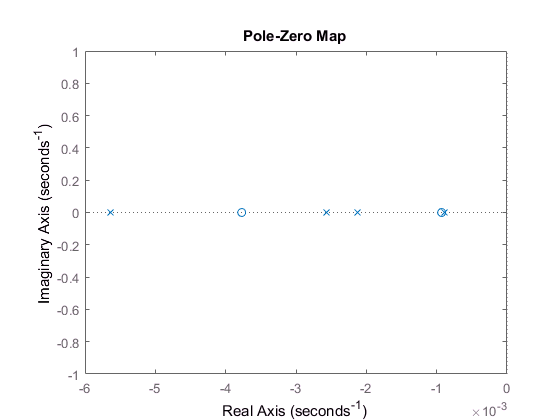

pzplot(sys)

Q_S = ctrb(sys) % Steuerbarkeitsmatrix

Q_S =     0.1740         0   -0.0010    0.0002    0.0000   -0.0000   -0.0000    0.0000
         0    0.0258    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
         0    0.0904         0   -0.0002         0    0.0000         0   -0.0000
    0.1044         0   -0.0002         0    0.0000         0   -0.0000         0


rang_Q_S = rank(Q_S)

rang_Q_S = 4

if rang_Q_S == rank(A), disp('Given System is controllable.');
else, disp('Given System is uncontrollable');
end

Given System is controllable.


Q_B = obsv(sys) % Beobachtbarkeitsmatrix

Q_B =     0.2000         0         0         0
         0    0.2000         0         0
   -0.0011         0    0.0005         0
         0   -0.0002         0    0.0001
    0.0000         0   -0.0000         0
         0    0.0000         0   -0.0000
   -0.0000         0    0.0000         0
         0   -0.0000         0    0.0000


rang_Q_B = rank(Q_B)

rang_Q_B = 4

if rang_Q_B == rank(A), disp('Given System is observable.');
else, disp('Given System is not observable.');
end

Given System is observable.


## Aufgabe 2

`Führen Sie eine RGA Analyse für niedrige Frequenzen durch und entwerfen Sie basierend darauf dezentrale PI Regler für beide Eingangs-/Ausgangspaare, sodass die Durchtrittsfrequenzen bei `$0\ldotp 2\frac{rad}{s}$` und die Phasenränder bei `$\frac{\pi }{4}$` liegen. Zeichen Sie das Bodediagramm für den offenen Regelkreis von Eingang `$u_1$` zu Ausgang `$y_1$` und veri�zieren durch horizontale und vertikale Linien im Diagramm, dass Durchtrittsfrequenz und Phasenrand eingehalten werden. Überprüfen Sie, ob der geschlossenen MIMO Regelkreis mit diesem dezentralen Regler stabil geregelt wird.`

G = tf(sys)


G =
 
  From input 1 to output...
         0.03479
   1:  ------------
       s + 0.005644
 
                7.621e-06
   2:  ----------------------------
       s^2 + 0.003019 s + 1.893e-06
 
  From input 2 to output...
                4.648e-05
   1:  ----------------------------
       s^2 + 0.008216 s + 1.451e-05
 
         0.005165
   2:  -------------
       s + 0.0008892
 
Continuous-time transfer function.



rga = G*inv(G)'


rga =
 
  From input 1 to output...
                                                                                                
       -s^11 + 0.0199 s^10 - 0.000129 s^9 + 2.637e-08 s^8 + 3.816e-09 s^7 - 2.057e-11 s^6       
                                                                                                
               + 4.458e-14 s^5 - 1.989e-17 s^4 - 8.796e-20 s^3 + 1.658e-22 s^2 - 1.14e          
                                                                                                
                                                                               -25 s + 2.826e-29
                                                                                                
   1:  -----------------------------------------------------------------------------------------
                                                                                                
       s^11 - 0.008609 s^10 - 4.584e-05 s^9 + 5.762e-07 s^8 - 2.667e-10 s^7 - 1.031e-11 s^

opts = pidtuneOptions('CrossoverFrequency',0.2,'PhaseMargin',45);
[K11, info1] = pidtune(G(1,1),'PI', opts)


K11 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 3.95, Ki = 0.836
 
Continuous-time PI controller in parallel form.



info1 =                 Stable: 1
    CrossoverFrequency: 0.2000
           PhaseMargin: 45


[K22, info2] = pidtune(G(2,2),'PI', opts)


K22 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 27.3, Ki = 5.5
 
Continuous-time PI controller in parallel form.



info2 =                 Stable: 1
    CrossoverFrequency: 0.2000
           PhaseMargin: 45


K = [K11, 0; 0, K22]


K =
 
  From input 1 to output...
       3.95 s + 0.8359
   1:  ---------------
              s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       27.26 s + 5.501
   2:  ---------------
              s
 
Continuous-time transfer function.



G_ol = G*K


G_ol =
 
  From input 1 to output...
       0.1374 s + 0.02908
   1:  ------------------
        s^2 + 0.005644 s
 
            3.01e-05 s + 6.37e-06
   2:  --------------------------------
       s^3 + 0.003019 s^2 + 1.893e-06 s
 
  From input 2 to output...
            0.001267 s + 0.0002557
   1:  --------------------------------
       s^3 + 0.008216 s^2 + 1.451e-05 s
 
       0.1408 s + 0.02841
   2:  ------------------
       s^2 + 0.0008892 s
 
Continuous-time transfer function.



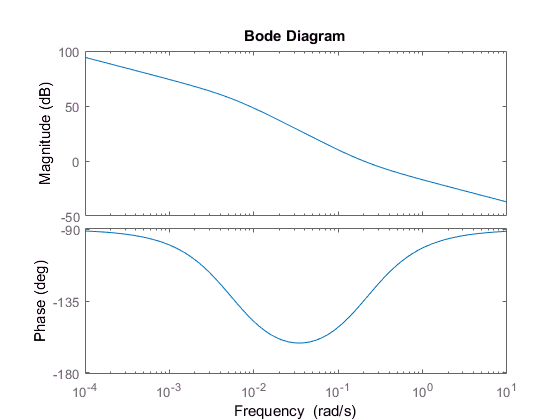

bode(G_ol(1,1))

if isstable(feedback(G_ol,eye(2),-1)), disp('The open loop system is stable.');
else, disp('The open loop system is not stable.');
end

The open loop system is not stable.


## Aufgabe 3

`Berechnen Sie die Sensitivitätsfunktionsmatrix `$S$` und komplementäre Sensitivitätsfunktionsmatrix `$T$` und visualisieren den Verlauf der Singulärwerte. Berechnen Sie die Bandbreiten der geschlossenen (dezentralen SISO) Kreise `$\omega_{BT,1\backslash 2}$` im Bezug auf `$T$`. Schätzen Sie über die Visualisierung ab, ob diese ähnlich zur Bandbreite im Bezug auf `$S$` ist.`

S = inv(eye(2)+G_ol)


S =
 
  From input 1 to output...
                                                                                                 
        s^10 + 0.1586 s^9 + 0.03091 s^8 + 0.0004946 s^7 + 3.014e-06 s^6 + 8.346e-09 s^5          
                                                                                                 
                                                  + 1.032e-11 s^4 + 4.407e-15 s^3 + 2.165e-32 s^2
                                                                                                 
   1:  -------------------------------------------------------------------------------------------
                                                                                                  
       s^10 + 0.296 s^9 + 0.081 s^8 + 0.009071 s^7 + 0.0009214 s^6 + 9.608e-06 s^5 + 3.28e-08 s^4 
                                                                                                  
                                       + 3.856e-11 s^3 + 1.453e-14 s^2 + 1.331e

T = S*G_ol


T =
 
  From input 1 to output...
                                                                                                    
       0.1374 s^24 + 0.09197 s^23 + 0.03533 s^22 + 0.009062 s^21 + 0.001634 s^20 + 0.0002162 s^19   
                                                                                                    
               + 1.929e-05 s^18 + 1.175e-06 s^17 + 2.742e-08 s^16 + 3.309e-10 s^15 + 2.385e-12 s^14 
                                                                                                    
               + 1.101e-14 s^13 + 3.368e-17 s^12 + 6.914e-20 s^11 + 9.511e-23 s^10 + 8.611e-26 s^9  
                                                                                                    
               + 4.911e-29 s^8 + 1.597e-32 s^7 + 2.257e-36 s^6 + 1.557e-50 s^5 - 3.974e-67 s^4      
                                                                                                    
                                                        

## Alternativ

.. mittels der integrierten Funktion `loopsens:`

loops = loopsens(G,K);

loops =         Si: [2×2 ss]
        Ti: [2×2 ss]
        Li: [2×2 tf]
        So: [2×2 ss]
        To: [2×2 ss]
        Lo: [2×2 tf]
       PSi: [2×2 ss]
       CSo: [2×2 ss]
     Poles: [8×1 double]
    Stable: 1


S = tf(loops.Si)


S =
 
  From input "du(1)" to output...
                                                                                                  
            s^8 + 0.1586 s^7 + 0.03091 s^6 + 0.0004946 s^5 + 3.014e-06 s^4 + 8.346e-09 s^3        
                                                                                                  
                                                                     + 1.032e-11 s^2 + 4.407e-15 s
                                                                                                  
   u(1):  ------------------------------------------------------------------------------------------
                                                                                                    
          s^8 + 0.296 s^7 + 0.081 s^6 + 0.009071 s^5 + 0.0009214 s^4 + 9.608e-06 s^3 + 3.28e-08 s^2 
                                                                                                    
                                                            

T = tf(loops.Ti)


T =
 
  From input "du(1)" to output...
                                                                                                
           0.1374 s^7 + 0.0501 s^6 + 0.008576 s^5 + 0.0009184 s^4 + 9.6e-06 s^3 + 3.279e-08 s^2 
                                                                                                
                                                                       + 3.855e-11 s + 1.453e-14
                                                                                                
   uC(1):  -------------------------------------------------------------------------------------
                                                                                                
           s^8 + 0.296 s^7 + 0.081 s^6 + 0.009071 s^5 + 0.0009214 s^4 + 9.608e-06 s^3           
                                                                                                
                                                        + 3.28e-08 s^2 + 3.856e-11 s +

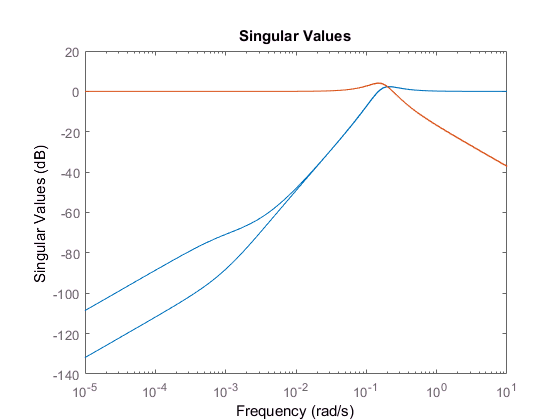

figure;
sigma(S) % blue one
hold on
sigma(T) % red one

wB_1 = bandwidth(T(1,1))

wB_1 = 0.2920

wB_2 = bandwidth(T(2,2))

wB_2 = 0.2927

Aus der Visualisierung ist abzulesen, dass $w_S \approx 0\ldotp 13$ist.

## Aufgabe 4

`Überprüfen Sie graphisch, ob der Regler die folgende Performanz einhält: `

`i) einen maximalen stationären Folgefehlers von 1dB (für Sprungantwort an den Eingängen) `

`ii) eine maximale Peakverstärkung von 20dB `

`iii) gutes Folgeverhalten in einer Bandbreite bis `$\omega_B =0\ldotp 5\frac{rad}{s}$ .

Eine typische Schrankenfunktion ist (laut Skript): $\omega_S =\frac{\frac{s}{M}+\omega_B }{s+\omega_B ∗Amp}$

Amp = db2mag(1) % conversion from dB

Amp = 1.1220

M = db2mag(20)

M = 10

wB = 0.5

wB = 0.5000

s = tf('s');
w_schranke = (s/M+wB)/(s+wB*Amp)


w_schranke =
 
     s + 5
  -----------
  10 s + 5.61
 
Continuous-time transfer function.



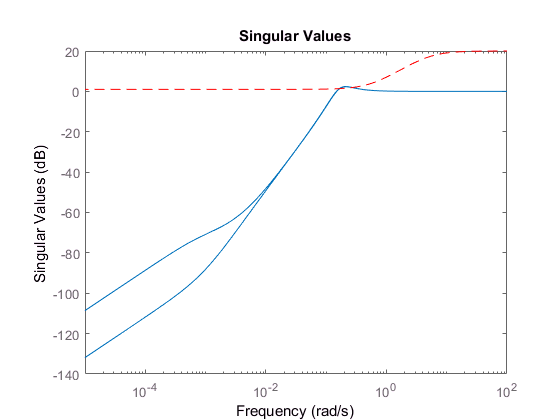

figure;
sigma(S)
hold on
sigma(1/w_schranke,'--r')

Wenn `sigma(S)` durchgehend unterhalb von `1/w_schranke` ist, dann sind die Performanzkritrien erfüllt. Hier ist das jedoch nicht der Fall! (Bei $\omega \approx 0\ldotp 2$)

## Aufgabe 5

`Überprüfen Sie graphisch, ob der Regler die folgende Performanz einhält: Einen niedrigen Energieaufwand, sodass `$\frac{\mathbf{U}}{\mathbf{W}}$` durch 20dB für alle Frequenzen beschränkt wird.`

w_u = db2mag(-20) % obere Schranke

w_u = 0.1000

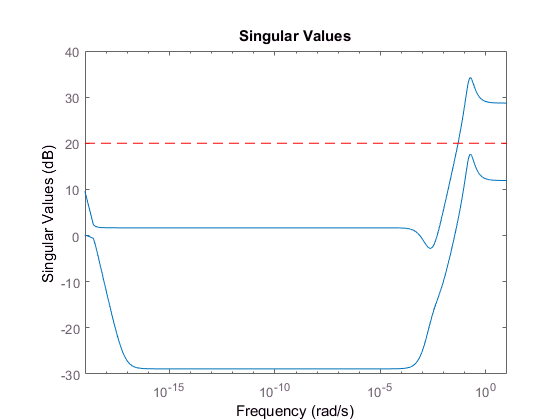

figure;
sigma(K*S)
hold on
sigma(1/w_u + 0*s,'r--')

Nur eine Funktion bleibt durchgehend unter 20dB, die andere nicht.

Die Pumpen sind leicht undicht und daher geht eine unbekannt Menge an Wasser über die Pumpen verloren. Diese Unsicherheit wird über einen unbekannten Eingang $d$ modelliert, der über die Matrix

N = [1/s, 1/(s+1); 1/(s+2), 1/(s+2)]


N =
 
  From input 1 to output...
       1
   1:  -
       s
 
         1
   2:  -----
       s + 2
 
  From input 2 to output...
         1
   1:  -----
       s + 1
 
         1
   2:  -----
       s + 2
 
Continuous-time transfer function.



eingekoppelt wird. Außerdem liefern die Sensoren nur ein verrauschtes Signal des Ausgangs. Dieses Rauschen wird durch ein sehr hochfrequentes $\mathbf{n}$ repräsentiert. Das Blockdiagramm in 2.1 zeigt das entsprechende Model mit Störung und Rauschen auf den Sensoren.

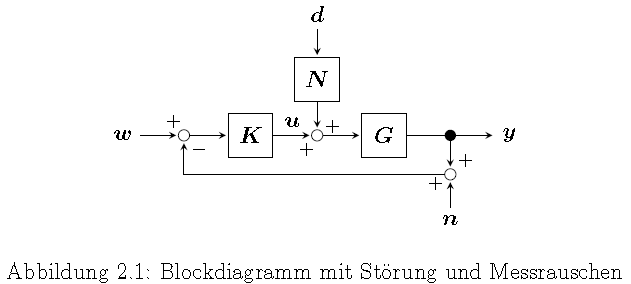

## Aufgabe 6

`Überprüfen Sie graphisch, ob der Regler die folgende Performanz einhält: Eine gute Rauschunterdrückung, sodass die Verstärkung des Rauschens `$\frac{\mathbf{y}}{\mathbf{n}}$` für hohe Frequenzen klein (-100 dB) und für niedrige Frequenzen gut (0dB) ist. Das Messrauschen setzt bei ungefähr `$\omega_C =100\text{ }\frac{rad}{s}$` ein.`

Es gilt für gute Rauschunterdrückung: $\frac{\mathbf{y}}{\mathbf{n}}\to 0\Leftrightarrow \mathbf{T}\left(j\omega \right)\to 0|_{\omega \to \infty }$

glf = db2mag(0) % gain low frequency

glf = 1

ghf = db2mag(-100) % gain high frequency

ghf = 1.0000e-05

wC = 100

wC = 100

w_T = (s/ghf+wC)/(s+wC*glf)


w_T =
 
     s + 0.001
  ---------------
  1e-05 s + 0.001
 
Continuous-time transfer function.



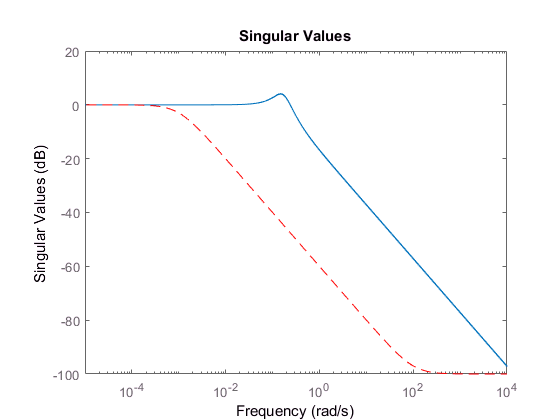

figure;
sigma(T)
hold on
sigma(1/w_T,'--r')

Prinzipell werden die geforderten Performanzschranken eingehalten, jedoch beträgt die Verstärkung bei $\omega_C =100\text{ }\frac{rad}{s}$ etwa -50dB anstatt der geforderten -100dB.

## Aufgabe 7

`�Überprüfen Sie graphisch, ob der Regler die folgende Performanz einhält: Störungen mit Frequenzen im Bereich `$0\ldotp 005\text{ }\frac{rad}{s}<\omega <0\ldotp 05\text{ }\frac{rad}{s}$` sollen bis zu 5dB gedämpft werden. Andere Frequenzen sind nicht wesentlich zu unterdrücken.`

Dämpfung zwischen $0\ldotp 005\text{ }\frac{rad}{s}<\omega <0\ldotp 05\text{ }\frac{rad}{s}$ sollen zu 5dB gedämpft werden: 5dB Verstärkung dort -> Bandpassfilter

wD = db2mag(-5)/(1+1/(s*0.005)+s/0.05)


wD =
 
          0.0001406 s
  ----------------------------
  0.005 s^2 + 0.00025 s + 0.05
 
Continuous-time transfer function.



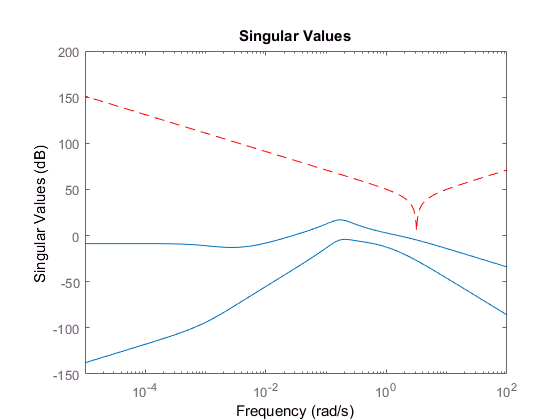

figure;
sigma(S*N)
hold on
sigma(1/wD,'r--')

Die undichte Stelle an den Pumpen wurde jetzt behoben, sodass Störunterdrückung nicht mehr im Reglerentwurf berücksichtigt wird.

## Aufgabe 8

`Berechnen Sie die generalisierte Strecke P und �üerpr�ufen Sie, ob `

`i) ein stabilisierender Regler existiert `

`ii) der Regler realisierbar ist `

`iii) der optimale Regler keine Pole oder Nullstellen auf der Imaginärachse kürzt. `

`Überprüfen Sie hierbei numerisch den relevanten Frequenzbereich.`

P = augw(G,w_schranke, w_u, w_T)


P =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8
   x1       -0.561           0           0           0    -0.06959           0           0           0
   x2            0      -0.561           0           0           0           0    -0.06243           0
   x3            0           0        -100           0       570.1           0           0           0
   x4            0           0           0        -100           0           0       511.5           0
   x5            0           0           0           0   -0.005644           0           0           0
   x6            0           0           0           0           0   -0.003019   -0.001939           0
   x7            0           0           0           0           0   0.0009766           0           0
   x8            0           0           0           0           0           0           0   -0.008216
   x9            0           0           0           0     

**Stabilisierbar? (Laut Lösung)**

nP = length(P.A)

nP = 10

qP = size(P.C,1)

qP = 8

q = size(C,1)

q = 2

rP = size(P.B,2)

rP = 4

r = size(B,2)

r = 2

iu1=1:rP-r

iu1 =      1     2


iu2=rP-r+1:rP

iu2 =      3     4


iy1=1:qP-q

iy1 =      1     2     3     4     5     6


iy2=qP-q+1:qP

iy2 =      7     8


rank_QS = rank(ctrb(P.A,P.B(:,iu2))) % P.B(:,iu2) = B2

rank_QS = 2

disp(string(rank_QS==nP))

false


n1 = nP, daraus folgt, dass das System stabilisierbar ist.

**Detektierbar? (Laut Lösung)**

rank_QB = rank(obsv(P.A,P.C(iy2,:)))

rank_QB = 4

disp(string(rank_QB==nP))

false


**Alternativ (laut Skript für Stabilisierbarkeit + Detektierbarkeit)**

if any(eig(A) >= 0), disp('There is no stabilizing controller!');
else, disp('There is a stabilizing controller!');
end

There is a stabilizing controller!


**Regler realisierbar?**

D12 = P.D(iy1,iu2)

D12 =          0         0
         0         0
    0.1000         0
         0    0.1000
         0         0
         0         0


D21 = P.D(iy2,iu1)

D21 =      1     0
     0     1


Haben `D12` und `D21` vollen Rang?

rank_D12 = rank(D12)

rank_D12 = 2

disp(string(rank_D12==min(size(D12))))

true


rank_D21 = rank(D21)

rank_D21 = 2

disp(string(rank_D21==min(size(D21))))

true


Da beide wahr sind, ist der Regler realisierbar.

**Kürzt der optimale Regler Pole oder Nullstellen auf der Imaginärachse?**

flog = true();
for w=logspace(1e-4,1e3,1e3)
    M1 = [P.A - 1i * w * eye(nP), P.B(:,iu1); P.C(iy2,:) D21];
    M2 = [P.A - 1i * w * eye(nP), P.B(:,iu2); P.C(iy1,:) D12];
    if rank(M1) ~= min(size(M1)) || rank(M2) ~= min(size(M2))
        flog = false();
        break;
    end
end
disp(string(flog))

false


## Aufgabe 9

`Führen Sie einen `$H_{\infty }$` Reglerentwurf f�ur o.g. Performanzen durch. Existiert ein Regler der diese einhält? Überprüfen Sie, diese Aussage auch graphisch, indem Sie die neuen Sensitivitäten in die Abbildungen aus Aufgabe 4-6 mit einzeichnen. Fügen Sie außerdem die Sensitivität für Aufgabe 7 mit dem neuen Regler in die entsprechende Abbildung ein. Wird die Performanz eingehalten, obwohl diese nicht im Reglerentwurf berücksichtigt wurde?`

[K_hinf, cL, gamma, info] = hinfsyn(P)


K_hinf =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8
   x1       -0.561   -8.83e-58           0  -8.177e-27  -1.388e-17           0   4.182e-26           0
   x2            0      -0.561           0           0           0           0  -6.939e-18           0
   x3            0           0        -100           0       570.1           0           0           0
   x4            0           0           0        -100           0           0       511.5           0
   x5       0.2025  -1.023e-07        6083   2.403e-05  -3.469e+04   3.472e-06      -9e-05   -0.002676
   x6      0.05063  -2.558e-08        1521   6.007e-06       -8673   -0.003018   -0.001961  -0.0006691
   x7            0           0           0           0           0   0.0009766           0           0
   x8   -1.481e-07      0.1013  -9.076e-06        2992   6.378e-05   -0.002963  -1.531e+04   -0.008216
   x9            0           0           0           0

gamma = 0.8900

info =        AS: [4×4 ss]
      KFI: []
      KFC: [16×2 double]
    GAMFC: 0.0070
    GAMFI: []


if gamma < 1, disp('Controllable!');
else, disp('Not controllable');
end

Controllable!


loops_hinf = loopsens(G,K_hinf);

loops_hinf =         Si: [2×2 ss]
        Ti: [2×2 ss]
        Li: [2×2 ss]
        So: [2×2 ss]
        To: [2×2 ss]
        Lo: [2×2 ss]
       PSi: [2×2 ss]
       CSo: [2×2 ss]
     Poles: [16×1 double]
    Stable: 1


S_hinf = loops_hinf.Si


S_hinf =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8
   x1    -0.005644           0           0           0           0           0   -0.001991   1.006e-09
   x2            0   -0.003019   -0.001939           0           0           0  -0.0004976   2.514e-10
   x3            0   0.0009766           0           0           0           0           0           0
   x4            0           0           0   -0.008216   -0.003716           0   1.456e-09  -0.0009958
   x5            0           0           0    0.003906           0           0           0           0
   x6            0           0           0           0           0  -0.0008892   7.279e-10  -0.0004979
   x7         7.08           0   9.441e-40           0       4.842   6.248e-40      -0.561   -8.83e-58
   x8            0           0       6.352           0           0       4.204           0      -0.561
   x9            0           0           0           0

T_hinf = loops_hinf.Ti


T_hinf =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8
   x1    -0.005644           0           0           0           0           0   -0.001991   1.006e-09
   x2            0   -0.003019   -0.001939           0           0           0  -0.0004976   2.514e-10
   x3            0   0.0009766           0           0           0           0           0           0
   x4            0           0           0   -0.008216   -0.003716           0   1.456e-09  -0.0009958
   x5            0           0           0    0.003906           0           0           0           0
   x6            0           0           0           0           0  -0.0008892   7.279e-10  -0.0004979
   x7         7.08           0   9.441e-40           0       4.842   6.248e-40      -0.561   -8.83e-58
   x8            0           0       6.352           0           0       4.204           0      -0.561
   x9            0           0           0           0

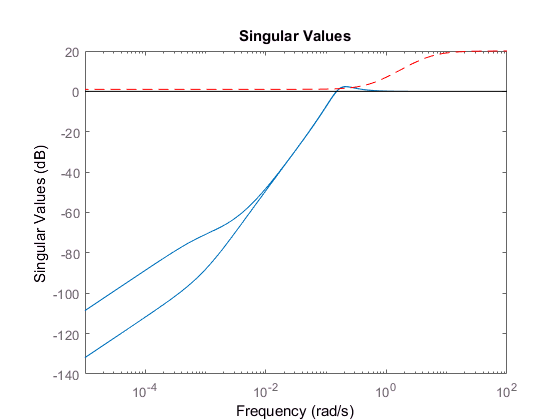

figure('Name','Aufgabe 4');
sigma(S)
hold on
sigma(1/w_schranke,'--r')
sigma(S_hinf,'k')

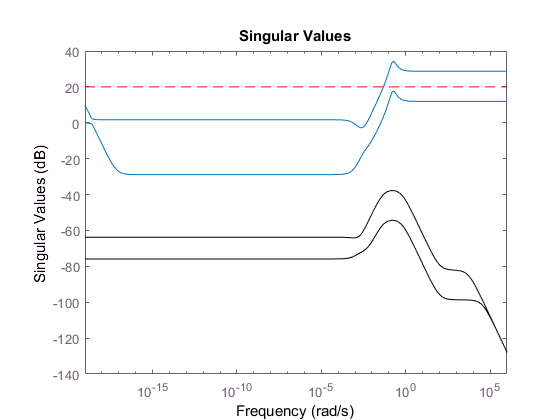

figure('Name','Aufgabe 5');
sigma(K*S)
hold on
sigma(1/w_u + 0*s,'r--')
sigma(K_hinf*S_hinf,'k')

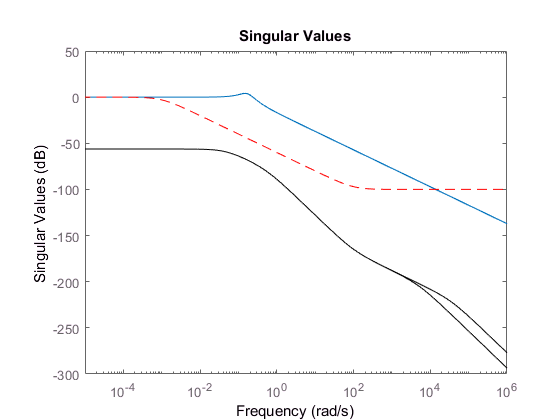

figure('Name','Aufgabe 6');
sigma(T)
hold on
sigma(1/w_T,'--r')
sigma(T_hinf,'k')

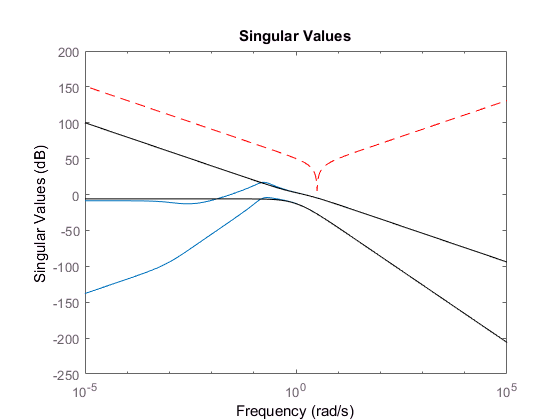

figure('Name','Aufgabe 7');
sigma(S*N)
hold on
sigma(1/wD,'r--')
sigma(S_hinf*N,'k')